clc %clears the command window
close all %close all windows
clear all %clears the workspace

Path = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/';
warning("off")

colaccX = 3;
colaccY = 4;
colaccZ = 5;

colgyroX = 10;
colgyroY = 11;
colgyroZ = 12;

colgravX = 21;
colgravY = 22;
colgravZ = 23;

M = 32;

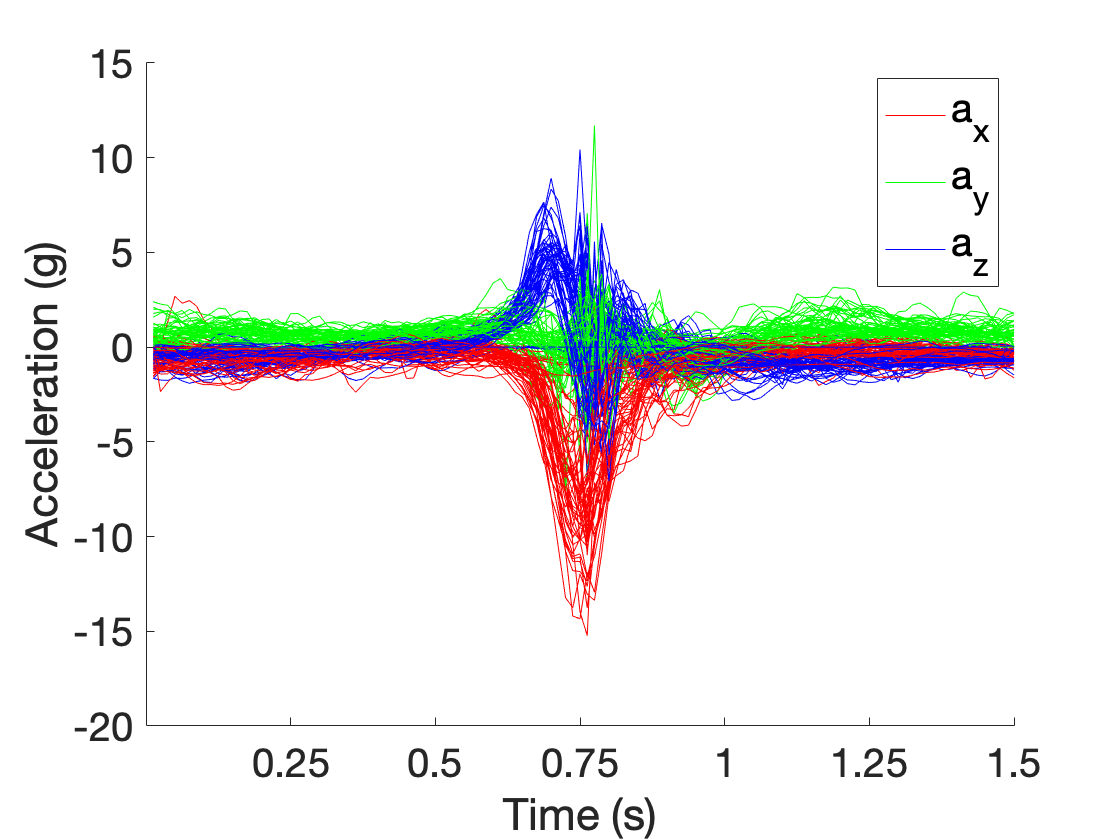

% Filename46 = string(Path) + 'Player 17/M.Me.S.17.1.csv';
% Filename47 = string(Path) + 'Player 17/M.Me.S.17.2.csv';
% Filename51 = string(Path) + 'Player 16/M.E.S.16.csv';
% Filename56 = string(Path) + 'Player 15/M.E.S.15.csv';
% Filename57 = string(Path) + 'Player 24/F.E.S.24.csv';
% Filename58 = string(Path) + 'Player 25/F.E.S.25.csv';


Filename46 = string(Path) + 'Player 17/M.Me.Fd.17.1.csv';
Filename47 = string(Path) + 'Player 17/M.Me.Fd.17.2.csv';
Filename51 = string(Path) + 'Player 17/M.Me.Fd.17.3.csv';
Filename56 = string(Path) + 'Player 16/M.E.Fd.16.csv';
Filename57 = string(Path) + 'Player 23/M.Me.Fd.23.1.csv';
Filename58 = string(Path) + 'Player 23/M.Me.Fd.23.2.csv';

% Filename46 = string(Path) + 'Player 17/M.Me.Bd.17.1.csv';
% Filename47 = string(Path) + 'Player 17/M.Me.Bd.17.2.csv';
% Filename51 = string(Path) + 'Player 17/M.Me.Bd.17.3.csv';
% Filename56 = string(Path) + 'Player 16/M.E.Bd.16.csv';
% Filename57 = string(Path) + 'Player 23/M.Me.Bd.23.1.csv';
% Filename58 = string(Path) + 'Player 23/M.Me.Bd.23.2.csv';

% Filename46 = string(Path) + 'Player 23/M.Me.FdV.23.1.csv';
% Filename47 = string(Path) + 'Player 23/M.Me.FdV.23.2.csv';
% Filename51 = string(Path) + 'Player 23/M.Me.FdV.23.3.csv';
% Filename56 = string(Path) + 'Player 24/F.E.FdV.24.csv';
% Filename57 = string(Path) + 'Player 25/F.E.FdV.25.csv';
% Filename58 = string(Path) + 'Player 23/M.Me.FdV.23.2.csv';

% Filename46 = string(Path) + 'Player 23/M.Me.BdV.23.1.csv';
% Filename47 = string(Path) + 'Player 23/M.Me.BdV.23.2.csv';
% Filename51 = string(Path) + 'Player 24/F.E.BdV.24.csv';
% Filename56 = string(Path) + 'Player 25/F.E.BdV.25.csv';
% Filename57 = string(Path) + 'Player 24/F.E.BdV.24.csv';
% Filename58 = string(Path) + 'Player 25/F.E.BdV.25.csv';

files_fdE = [Filename46,Filename47, Filename51, Filename56, Filename57, Filename58];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fdE, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 39.9949

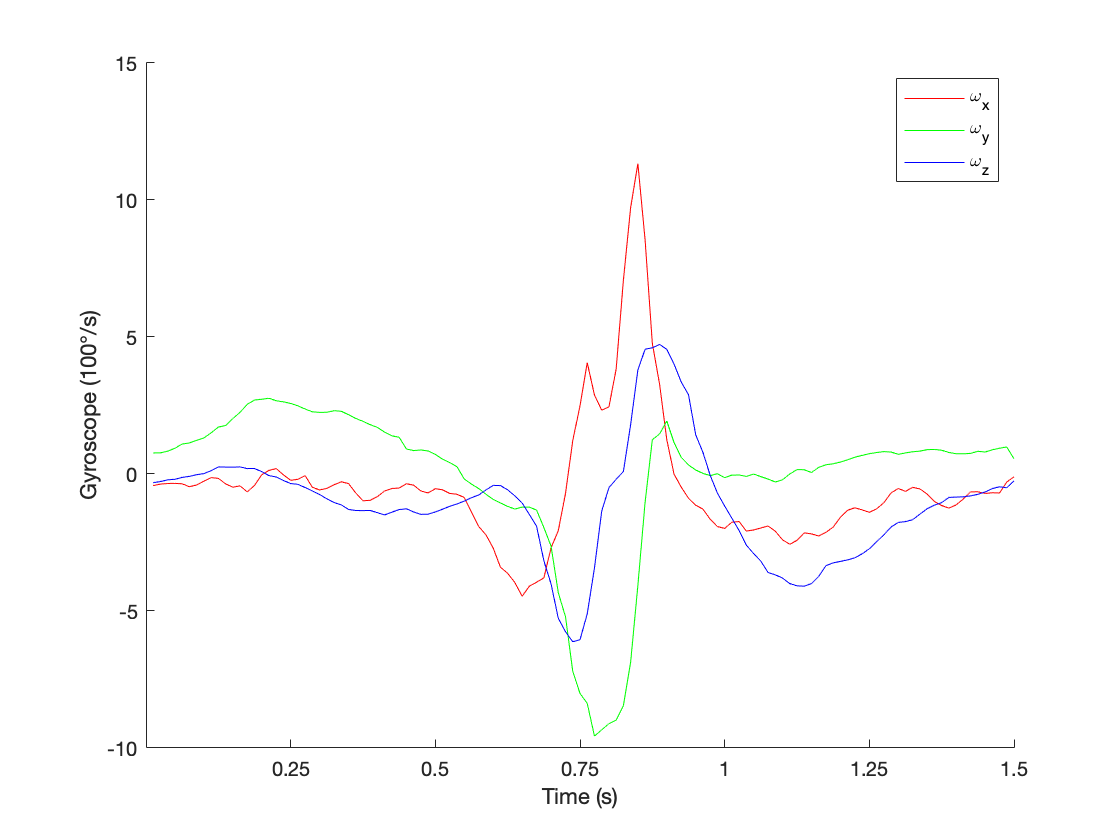

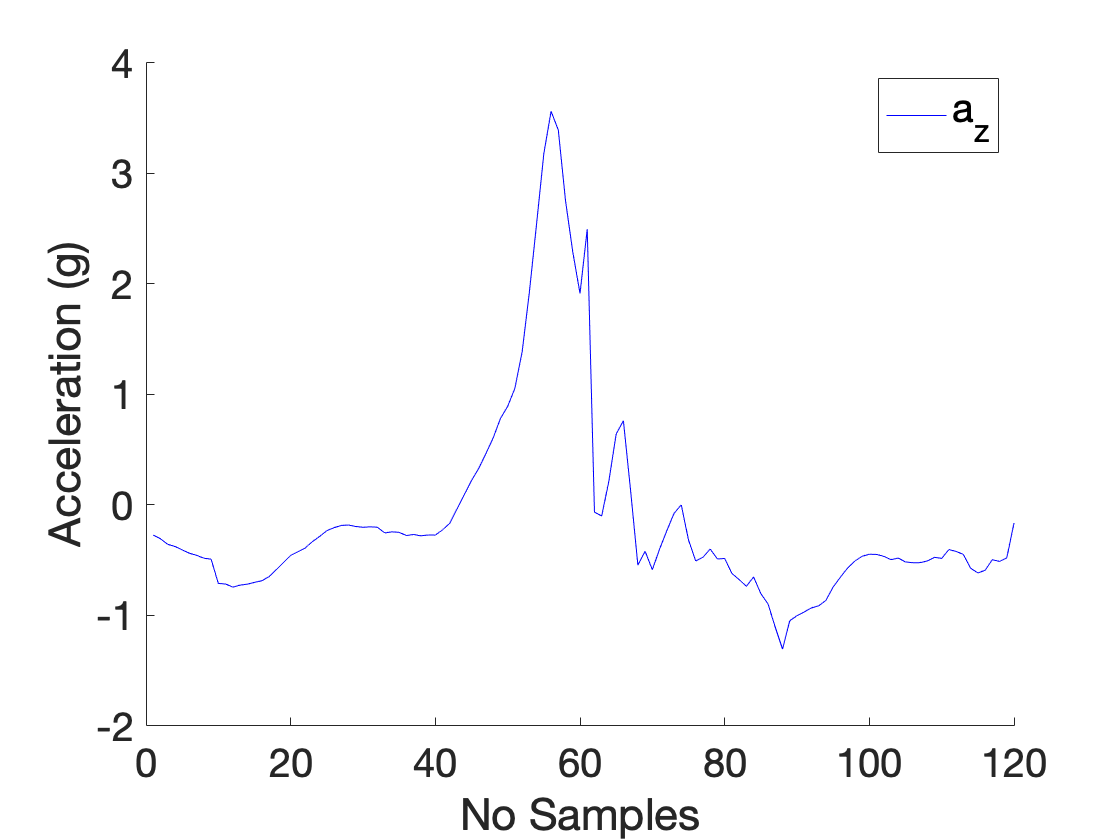

[template_gyroX,template_gyroY,template_gyroZ,template_accelX,template_accelY,template_accelZ] = template_shots(AllfGyroX,AllfGyroY,AllfGyroZ, AllfAccelX,AllfAccelY,AllfAccelZ);

[consistency_gyroX,consistency_gyroY,consistency_gyroZ,consistency_accelX,consistency_accelY,consistency_accelZ] = consistency_evaluation(template_gyroX, template_gyroY, template_gyroZ, template_accelX,template_accelY,template_accelZ,AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,faStd,fgStd);

Error using consistency_evaluation
Too many input arguments.

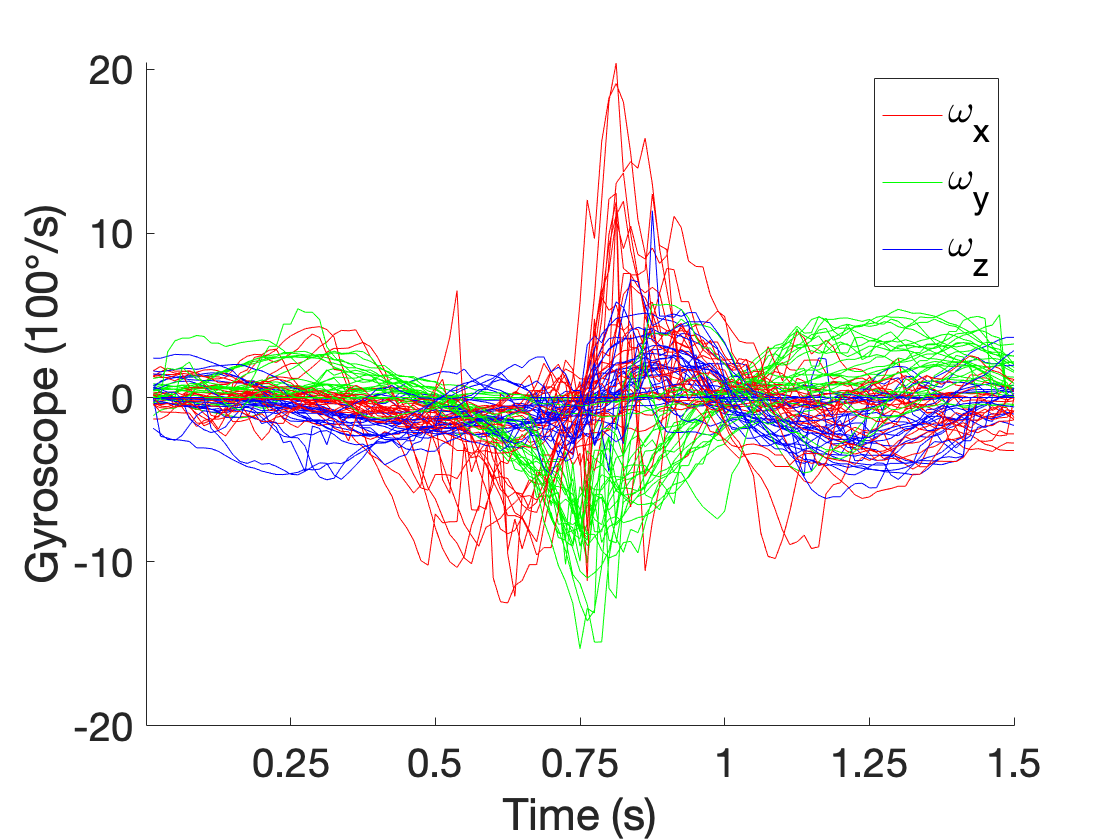

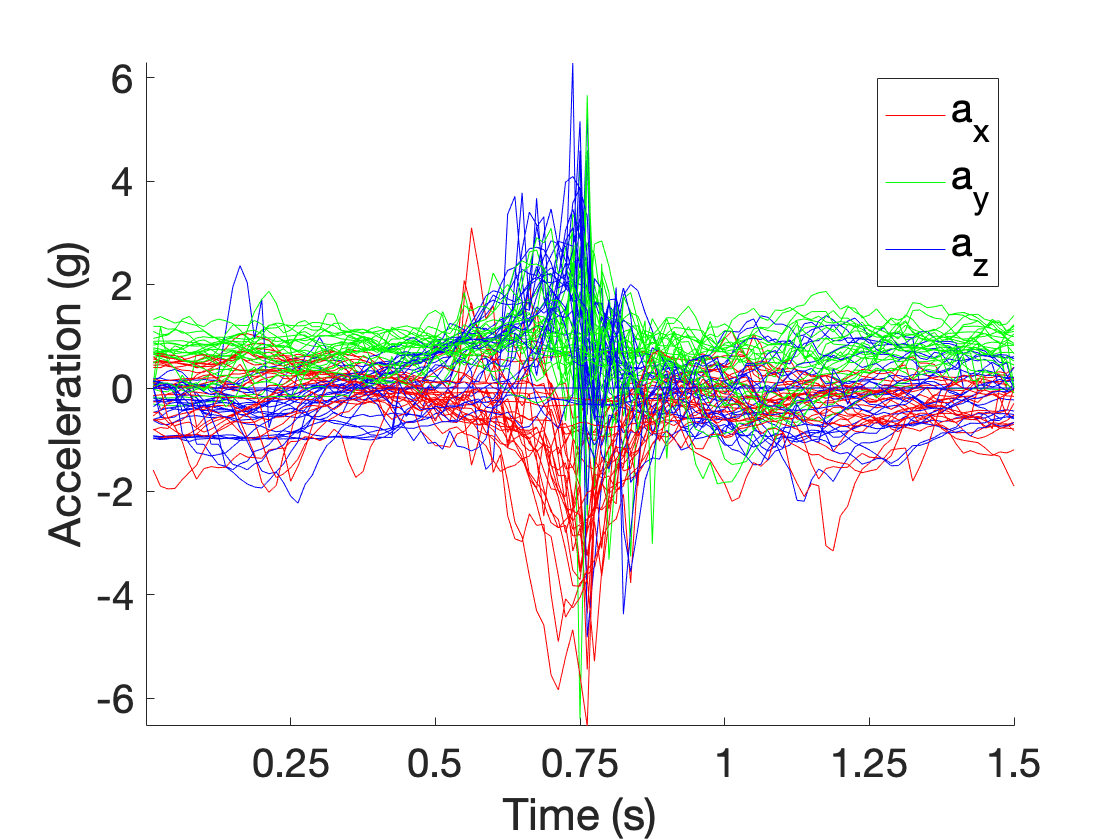

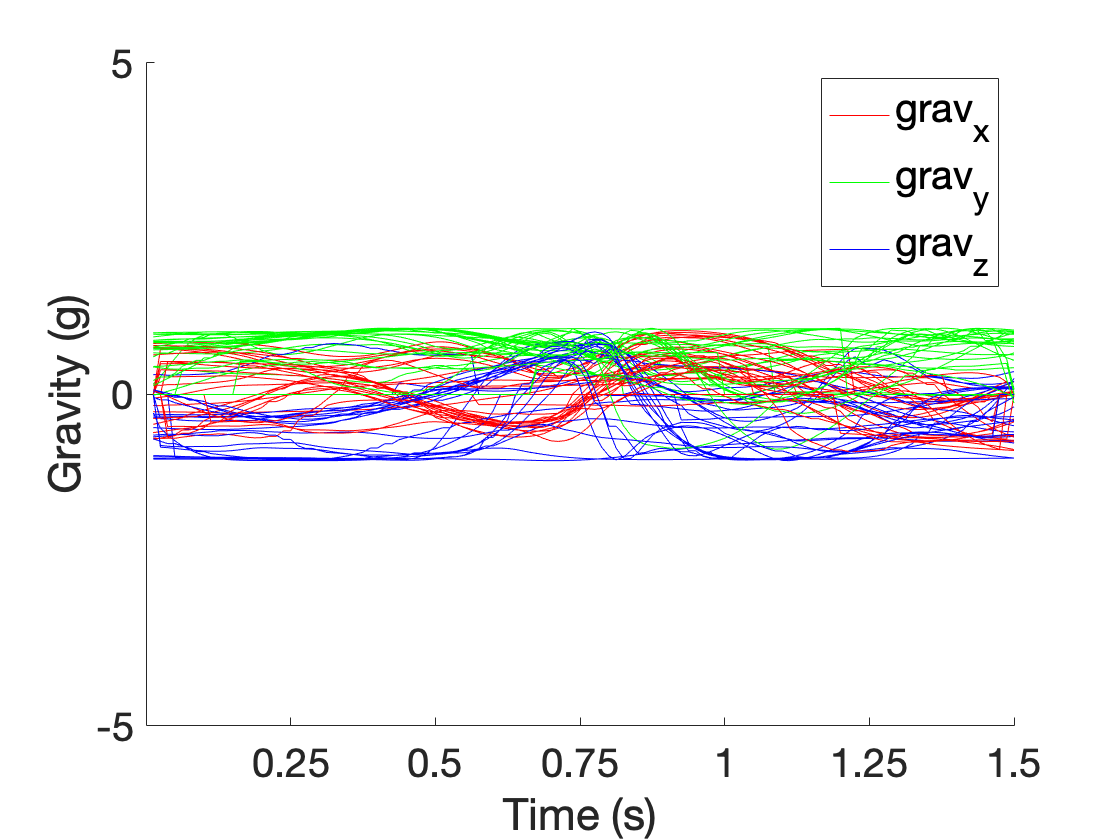

% Filename48 = string(Path) + 'Player 21/F.B.S.21.1.csv';
% Filename49 = string(Path) + 'Player 21/F.B.S.21.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.S.21.3.csv';
% Filename52 = string(Path) + 'Player 22/M.B.S.22.1.csv';
% Filename53 = string(Path) + 'Player 22/M.B.S.22.2.csv';
% Filename54 = string(Path) + 'Player 26/F.B.S.26.1.csv';
% Filename55 = string(Path) + 'Player 26/F.B.S.26.2.csv';
% 
Filename48 = string(Path) + 'Player 20/F.B.Fd.20.1.csv';
Filename49 = string(Path) + 'Player 20/F.B.Fd.20.2.csv';
Filename50 = string(Path) + 'Player 21/F.B.Fd.21.1.csv';
Filename52 = string(Path) + 'Player 22/M.B.Fd.22.1.csv';
Filename53 = string(Path) + 'Player 26/F.B.Fd.26.1.csv';
Filename54 = string(Path) + 'Player 26/F.B.Fd.26.2.csv';
Filename55 = string(Path) + 'Player 27/F.B.Fd.27.1.csv';

% Filename48 = string(Path) + 'Player 20/F.B.Bd.20.1.csv';
% Filename49 = string(Path) + 'Player 20/F.B.Bd.20.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.Bd.21.1.csv';
% Filename52 = string(Path) + 'Player 21/F.B.Bd.21.2.csv';
% Filename53 = string(Path) + 'Player 22/M.B.Bd.22.1.csv';
% Filename54 = string(Path) + 'Player 26/F.B.Bd.26.1.csv';
% Filename55 = string(Path) + 'Player 27/F.B.Bd.27.1.csv';

% Filename48 = string(Path) + 'Player 21/F.B.FdV.21.1.csv';
% Filename49 = string(Path) + 'Player 21/F.B.FdV.21.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.FdV.21.2.csv';
% Filename52 = string(Path) + 'Player 26/F.B.FdV.26.1.csv';
% Filename53 = string(Path) + 'Player 26/F.B.FdV.26.2.csv';
% Filename54 = string(Path) + 'Player 27/F.B.FdV.27.1.csv';
% Filename55 = string(Path) + 'Player 27/F.B.FdV.27.2.csv';

% Filename48 = string(Path) + 'Player 21/F.B.BdV.21.1.csv';
% Filename49 = string(Path) + 'Player 21/F.B.BdV.21.2.csv';
% Filename50 = string(Path) + 'Player 26/F.B.BdV.26.1.csv';
% Filename52 = string(Path) + 'Player 26/F.B.BdV.26.2.csv';
% Filename53 = string(Path) + 'Player 27/F.B.BdV.27.1.csv';
% Filename54 = string(Path) + 'Player 27/F.B.BdV.27.2.csv';
% Filename55 = string(Path) + 'Player 21/F.B.BdV.21.2.csv';


files_fdB = [Filename48,Filename49,Filename50,Filename52,Filename53,Filename54,Filename55];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fdB, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMaxB,faMinB,faMeanB,faStdB,faAreaB,fgMaxB,fgMinB,fgMeanB,fgStdB,fgAreaB,fgravMaxB,fgravMinB,fgravMeanB,fgravStdB,fgravAreaB] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 21.5223

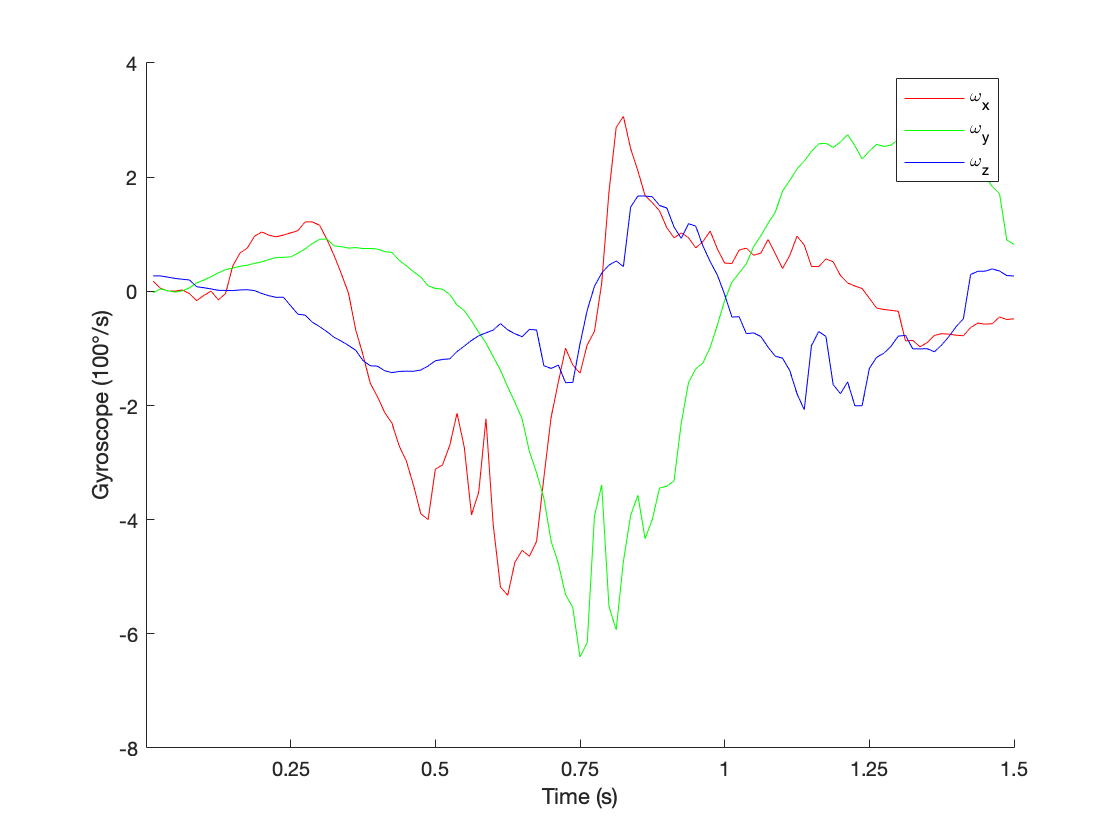

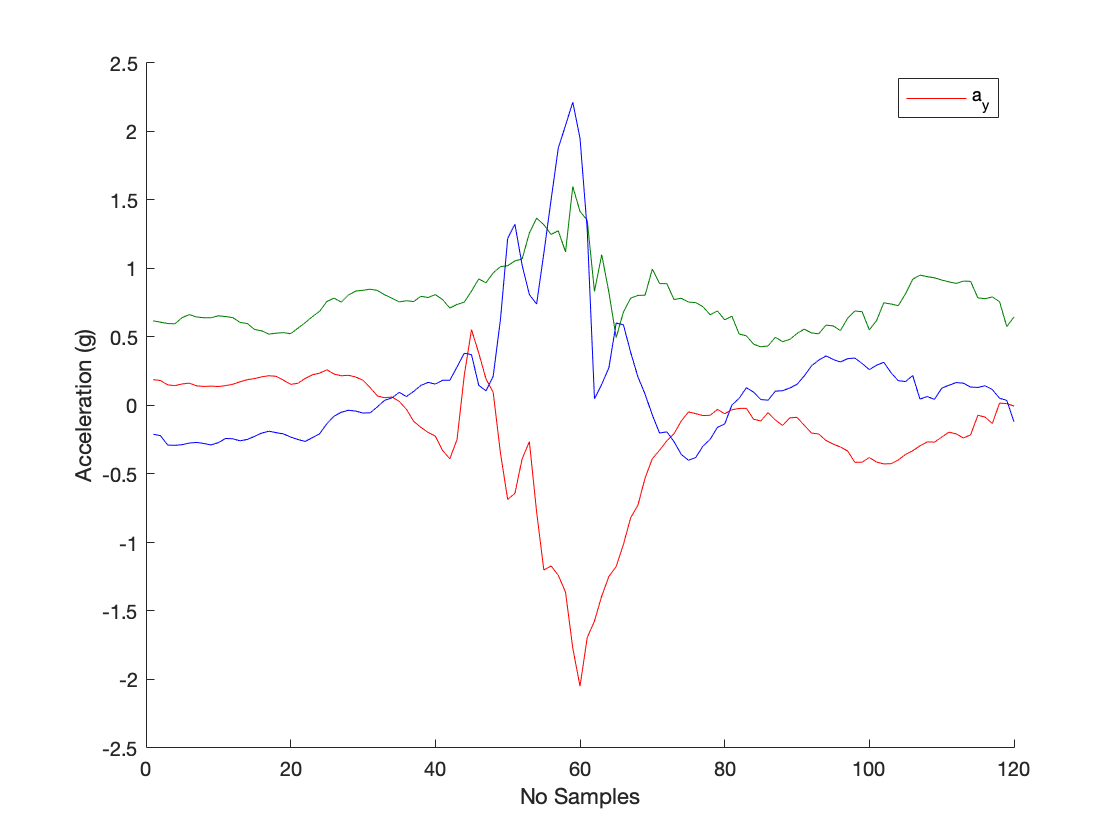

[Btemplate_gyroX,Btemplate_gyroY,Btemplate_gyroZ,Btemplate_accelX,Btemplate_accelY,Btemplate_accelZ] = template_shots(AllfGyroX,AllfGyroY,AllfGyroZ, AllfAccelX,AllfAccelY,AllfAccelZ);

[consistency_gyroX,consistency_gyroY,consistency_gyroZ,consistency_accelX,consistency_accelY,consistency_accelZ] = consistency_evaluation(template_gyroX, template_gyroY, template_gyroZ, template_accelX,template_accelY,template_accelZ,AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,faStd,fgStd);

consistency_gyroX_total = 1.6614

consistency_gyroY_total = 2.0724

consistency_gyroZ_total = 1.7604

consistency_accelX_total = 1.2462

consistency_accelY_total = 0.6102

consistency_accelZ_total = 0.6688

% N = 14
% 
% figure
% time = linspace(1,120,120)
% scatter(time, AllfGyroX(:,N),'o','red')
% hold on
% plot(time, template_gyroX)
% 
% scatter(time, AllfGyroY(:,N),'o','green')
% hold on
% plot(time, template_gyroY,'green')
% 
% scatter(time, AllfGyroZ(:,N),'o','blue')
% hold on
% plot(time, template_gyroZ,'blue')
% legend('\omega_{x}', '\omega_{x, template}', '\omega_{y}', '\omega_{y,template}', '\omega_{z}', '\omega_{z,template}')
% xlabel('No Sample')
% ylabel('Rotation rate (100deg/s)')
% hold off

% N = 9
% 
% figure
% time = linspace(1,120,120)
% scatter(time, AllfGyroX(:,N),'o','red')
% hold on
% plot(time, template_gyroX)
% 
% scatter(time, AllfGyroY(:,N),'o','green')
% hold on
% plot(time, template_gyroY,'green')
% 
% scatter(time, AllfGyroZ(:,N),'o','blue')
% hold on
% plot(time, template_gyroZ,'blue')
% legend('\omega_{x}', '\omega_{x, template}', '\omega_{y}', '\omega_{y,template}', '\omega_{z}', '\omega_{z,template}')
% xlabel('No Sample')
% ylabel('Rotation rate (100deg/s)')
% hold off

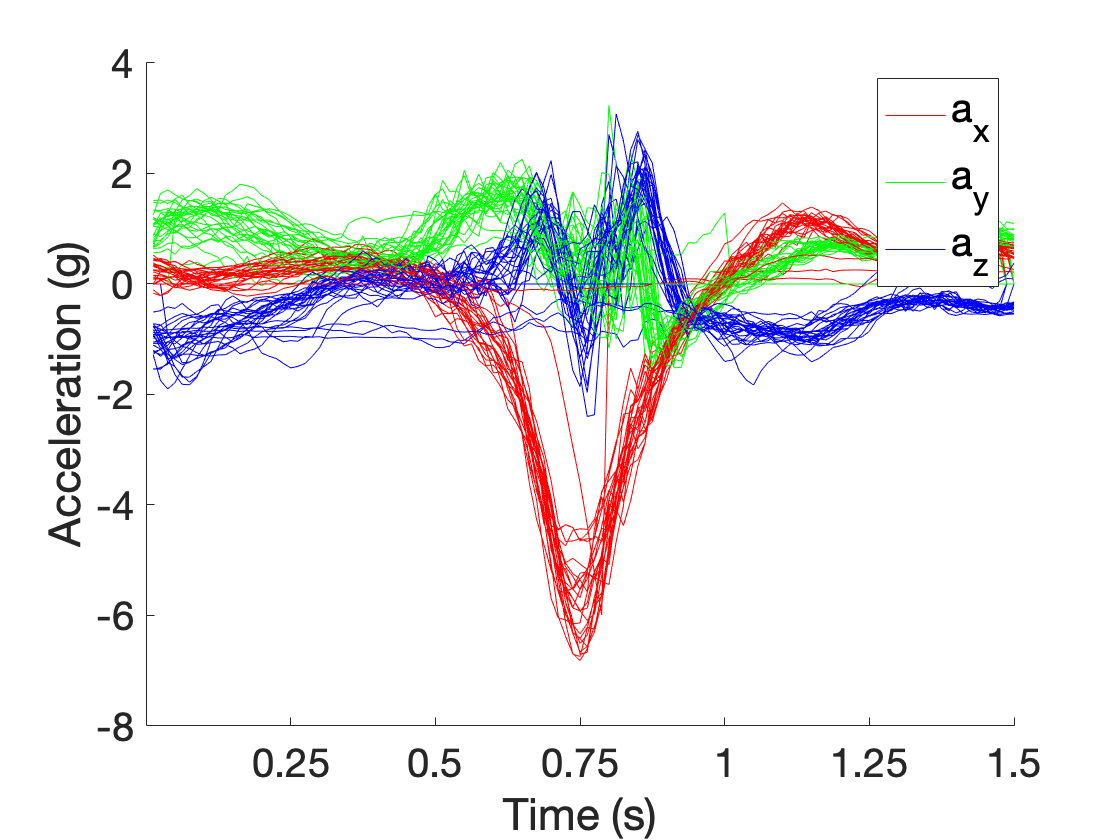

Filename1= string(Path) + 'Misses/Misses.1.csv';
Filename2= string(Path) + 'Misses/Misses.2.csv';
Filename3= string(Path) + 'Misses/Misses.3.csv';
Filename4= string(Path) + 'Misses/Misses.4.csv';

files_fd_Misses = [Filename1, Filename2, Filename3, Filename4];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd_Misses,32, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 35.2720

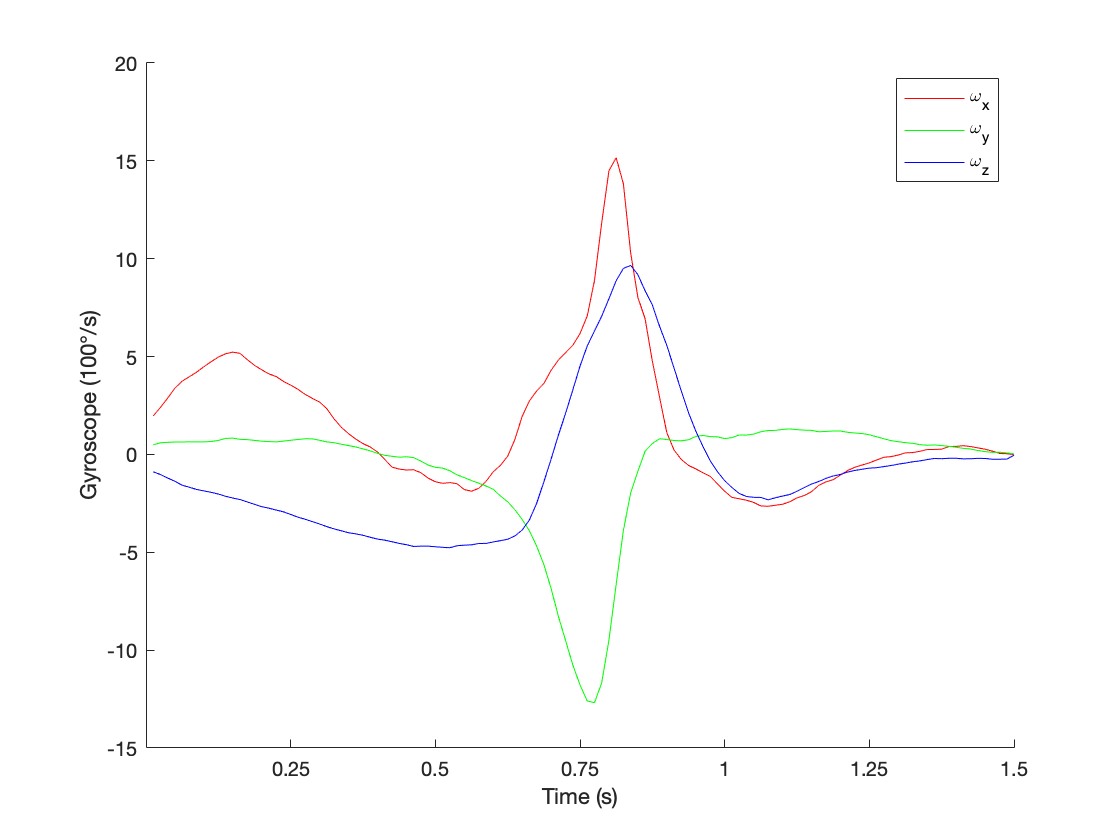

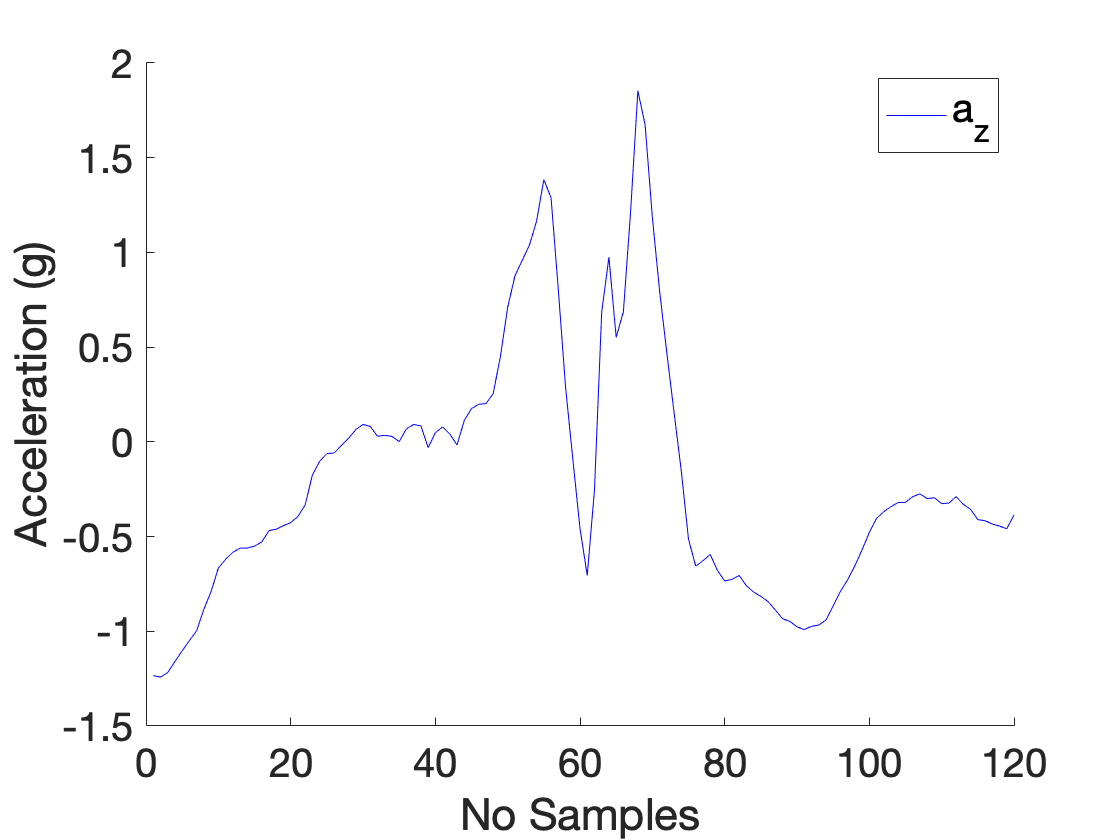

[Btemplate_gyroX,Btemplate_gyroY,Btemplate_gyroZ,Btemplate_accelX,Btemplate_accelY,Btemplate_accelZ] = template_shots(AllfGyroX,AllfGyroY,AllfGyroZ, AllfAccelX,AllfAccelY,AllfAccelZ);

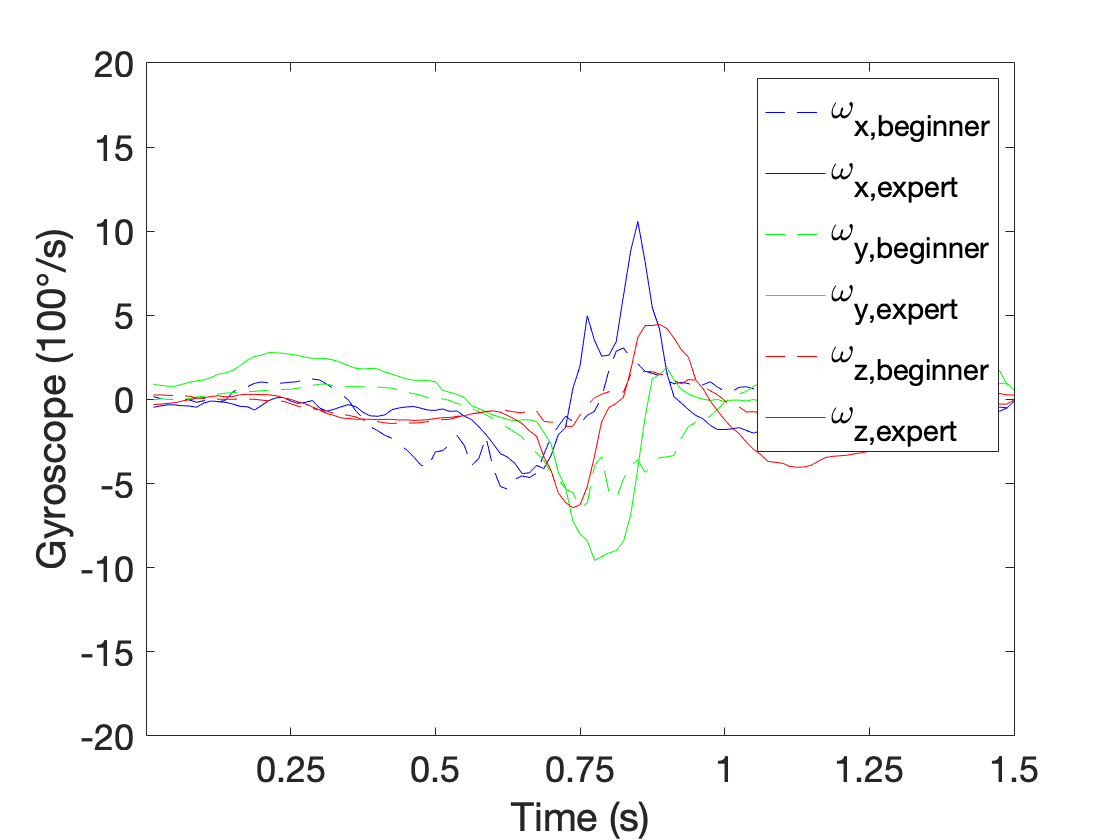

figure
plot(Btemplate_gyroX, '--','Color','blue')
hold on
plot(template_gyroX,'Color','blue')
plot(Btemplate_gyroY, '--','Color','green')
plot(template_gyroY,'Color','green')
plot(Btemplate_gyroZ, '--','Color','red')
plot(template_gyroZ,'Color','red')

xlabel('Time (s)','FontSize', 18); %x-axis label 
set(gca,'XTickLabel',{'0.25','0.5','0.75','1','1.25','1.5',},'XTick',[20 40 60 80 100 120]);
legend('\omega_{x,beginner}', '\omega_{x,expert}','\omega_{y,beginner}', '\omega_{y,expert}','\omega_{z,beginner}','\omega_{z,expert}','FontSize', 18)
ylabel('Gyroscope (100°/s)','FontSize', 18); %y-asix label
set(gca,'FontSize',18)
ylim([-20 20])
hold off

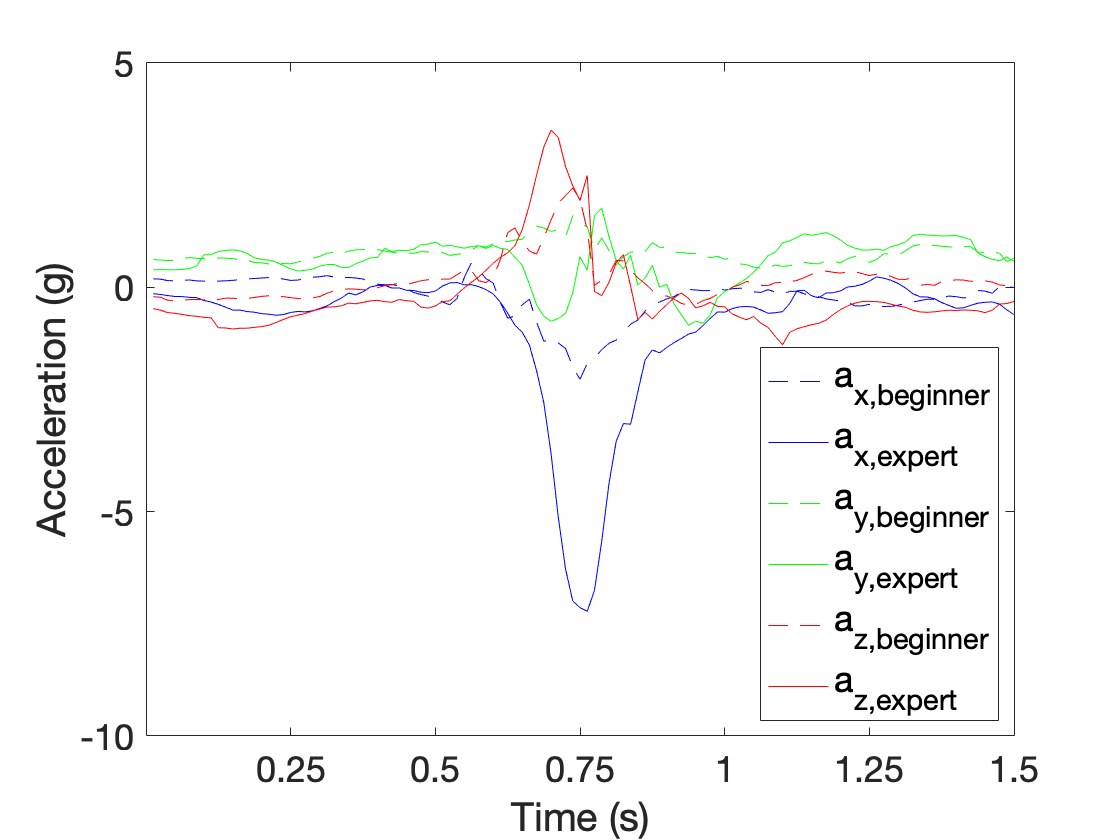

figure
plot(Btemplate_accelX, '--','Color','blue')
hold on
plot(template_accelX,'Color','blue')
plot(Btemplate_accelY, '--','Color','green')
plot(template_accelY,'Color','green')
plot(Btemplate_accelZ, '--','Color','red')
plot(template_accelZ,'Color','red')

xlabel('Time (s)','FontSize', 18); %x-axis label 
set(gca,'XTickLabel',{'0.25','0.5','0.75','1','1.25','1.5',},'XTick',[20 40 60 80 100 120]);
legend('a_{x,beginner}', 'a_{x,expert}','a_{y,beginner}', 'a_{y,expert}','a_{z,beginner}','a_{z,expert}','FontSize', 18,'Location','southEast')
ylabel('Acceleration (g)','FontSize', 18); %y-asix label
set(gca,'FontSize',18)
ylim([-10 5])
hold off